clear; clc; close all;

1

delta_range = logspace(5,-20, 1000);
x_num = ones(size(delta_range));
x_ex = 1;
P1=[0.0 1.0];
for i=1:numel(delta_range)
    delta = delta_range(i);
    P2=[delta, 1.0+delta];
%     x_num(i)=lineintersection(P1,P2);
    x_num(i) = delta/((1.0+delta)-1.0);
end

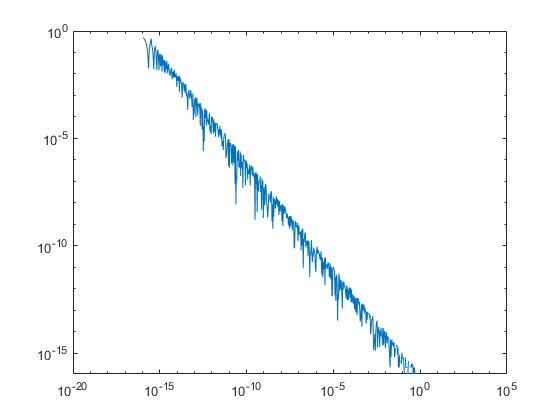

loglog(delta_range, abs(x_ex - x_num))

2

x_node = [0.0 1.0 2.0 3.0 4.0];
f_node = [0.000000000000 0.031250000000 0.131687242798 0.237304687500 0.327680000000];
x = 0.6;
n = 1;
f_L1 = LagrangePolynom(x,n,x_node,f_node)

f_L1 = 0.0188

f_dL1 = LagrangeDerivPolynom(x,n,x_node,f_node)

f_dL1 = 0.0313

n = 4;
f_L4 = LagrangePolynom(x,n,x_node,f_node)

f_L4 = 0.0054

f_dL4 = LagrangeDerivPolynom(x,n,x_node,f_node)

f_dL4 = 0.0466

x_range = linspace(0,4,81);
f_ex = (x_range./(1+x_range)).^5;
fd_ex = (5.*x_range.^4)./(x_range + 1).^6;
n = 80;
f_L80 = LagrangePolynom(x,n,x_range,f_ex)

f_L80 = 0.0074

f_dL80 = LagrangeDerivPolynom(x,n,x_range,f_ex)

f_dL80 = 0.0386

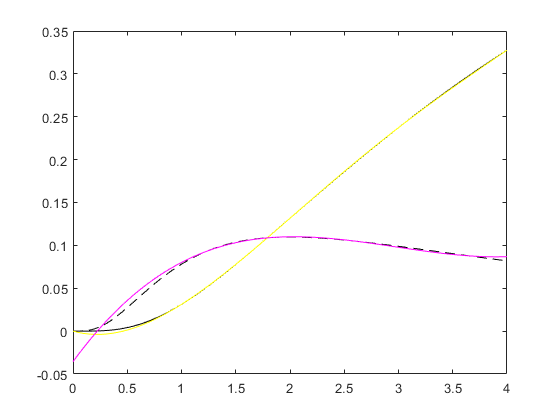

n = 4;
f_L4 = zeros(1,numel(x_range));
f_dL4 = zeros(1,numel(x_range));
for i=1:numel(x_range)
    f_L4(i) = LagrangePolynom(x_range(i),n,x_node,f_node);
    f_dL4(i) = LagrangeDerivPolynom(x_range(i),n,x_node,f_node);
end
plot(x_range,f_ex,'-k',x_range,fd_ex,'--k',x_range,f_L4,'-y',x_range,f_dL4,'-m');

function x_num = lineintersection(P1,P2)
    syms x y;
    x_num = solve(y==2, (x-P1(1))/(P2(1)-P1(1))==(y-P1(2))/(P2(2)-P1(2))).x;
end

function wert_basis = LagrangeBasis(x,n,i,x_node)
    x_i = x_node(i);
    x_node(i) = [];
    wert_basis = prod(x-x_node)/prod(x_i-x_node);
end

function wert_poly = LagrangePolynom(x,n,x_node,f_node)
    x_node = x_node(1:n+1);
    f_node = f_node(1:n+1);
    wert_basis = zeros(1, n+1);
    for i=1:n+1
        wert_basis(i) = LagrangeBasis(x,n,i,x_node);
    end
    wert_poly = sum(f_node.*wert_basis);
end

function wert_dbasis = LagrangeDerivBasis(x,n,i,x_node)
    x_i = x_node(i);
    x_node(i) = [];
    wert_dbasis = 0;
    for m=1:n
        x_m = x_node(m);
        x_k = x_node;
        x_k(m) = [];
        wert_dbasis = wert_dbasis + 1/(x_i-x_m)*prod((x-x_k))/prod((x_i-x_k));
    end
end

function wert_dpoly = LagrangeDerivPolynom(x,n,x_node,f_node)
    x_node = x_node(1:n+1);
    f_node = f_node(1:n+1);
    wert_dbasis = zeros(1, n+1);
    for i=1:n+1
        wert_dbasis(i) = LagrangeDerivBasis(x,n,i,x_node);
    end
    wert_dpoly = sum(f_node.*wert_dbasis);
end